# 钙行为

## Oir配准并输出Tiff

选择输入输出。运行本节之前，请先将所有OIR文件序列放在同一个目录下。

MovingPaths=MATLAB.UITools.OpenFileDialog(Filter='Olympus OIR|*.oir',Multiselect=true,Title='选择要配准的 Olympus OIR 文件');
OutputDirectory=uigetdir('.','选择输出目录');

执行文件内配准

此函数性能关键，有大量可选名称值参数，需要根据计算机硬件状况进行调整以达到最佳性能。请仔细阅读文档，优化参数。

UniExp.BatchOirRegisterTiff(MovingPaths,OutputDirectory,BlockSize=26,Parallel=9,CacheDirectory=fullfile('D:',getenv('USERNAME'),'缓存'),BaseRegisterToDisk=false,WatchDogMinutes=3);

初级配准并收集Tags……
Worker 3: 
  警告: GPU内存不足，启动自适应分块算法，目前分块：2
Worker 1: 
  警告: GPU内存不足，启动自适应分块算法，目前分块：2
开始执行金字塔配准……
文件1/3：D:\张天夫\配准测试\yqn0111.202403181921.LAuAuw.4%350V22%350V.oir
文件2/3：D:\张天夫\配准测试\yqn0111.202403190720.AudioWater.8%350V40%350V.oir
文件3/3：D:\张天夫\配准测试\yqn0111.202403200714.AudioWater.6%350V35%350V.oir
应用配准结果，输出平均图……
2024-03-23 20:16:52 文件1/3 帧339/339
2024-03-23 20:16:54 文件2/3 帧339/339
2024-03-23 20:16:56 文件3/3 帧339/339


如果所有文件都输出完毕，程序却不结束，请检查是否有弹出对话框被压在下面等待确认。

此方法将在输出目录为每个OIR生成一个仅包含非标通道的、文件内已配准的TIFF，和一个全时间轴平均值图像。此外还生成记录元数据的UniExp数据库。

平均值图像用于下一步圈ROI，作为文件间配准的基准晃动图。

用ImageJ打开首日固定图和平均值图像，为每个文件的每个Z层圈出数量相同的标志性特征ROI（细胞、血管端等）。

圈ROI是一个玄学步骤，原则上应该期望固定图中圈出的特征ROI在配准目标图中都能找到精确对应的位置并圈为ROI。一般建议数量3个左右，尽量在图像四角均匀分布，尽可能小，避免在其它细胞的连线上或围成的多边形内圈，这种圈容易造成负面干扰作用。

同一个文件圈出的ROI，无论Z层，保存到同一个RoiSet。不同文件的ROI保存到不同的RoiSet。RoiSet文件名排序应当与图像文件相同，不同文件之间对应的ROI应该具有相同的序号。

比较简单的方法是为每个图各圈一个ROI文件，但这要求你选择的特征ROI在所有图中都存在且位置清晰。如果不能保证所有图中都存在相同的高质量ROI，还可以用配对法。即，不要求每个晃动图的ROI都相同，而是为每个晃动图ROI文件各自配一个固定图的ROI文件。例如有10张晃动图，你就要圈10个晃动ROI文件，然后为每个文件各自圈一个匹配的固定图ROI文件，最终得到10个晃动ROI文件和10个固定ROI文件。固定-晃动配对ROI文件必须具有相同的ROI特征，但不同对之间则不需要。

然后选择文件：

FixedRoi=MATLAB.UITools.OpenFileDialog(Filter='ImageJ RoiSet|*.zip',Multiselect=true,Title='选择从第一天固定图圈出的RoiSet')';
MovingRoi=MATLAB.UITools.OpenFileDialog(Filter='ImageJ RoiSet|*.zip',Multiselect=true,Title='选择所有从晃动图圈出的RoiSet')';
MovingImage=MATLAB.UITools.OpenFileDialog(Filter='TIFF or OIR|*.tif;*.oir',Multiselect=true,Title='选择所有晃动图')';

MovingSamples应当是平均值图像或每日参照图等单帧图像，而不是具有时间跨度的原始视频。如果采用配对ROI，请检查FixedRois、MovingRois和MovingSamples是否具有一一对应的顺序。如果发现卡在这一段无法运行下去，请最小化MATLAB窗口，检查是否打开了正在等待你选择文件的对话框。

执行试配准，返回跨文件变换矩阵。

if isscalar(FixedRoi)
	TransMatrix = UniExp.RoiRegister(table(MovingRoi,MovingImage),FixedRoi,OutputDirectory);
else
	TransMatrix = UniExp.RoiRegister(table(MovingRoi,MovingImage,FixedRoi),OutputDirectory);
end
save(fullfile(OutputDirectory,'变换矩阵.mat'),'TransMatrix');

在OutputDirectory会生成试配图像，用ImageJ打开试配图像，和固定图像比对，看配准效果如何。如果效果不满意，可以重新圈ROI再试，重圈时可优先圈那些让你感觉明显不满意的位点，而舍弃那些模棱两可的位点。

如果试配满意，下面将使用返回的TransMatrix变换矩阵进行文件间配准。

文件间矩阵变换配准

选择文件

TiffPath=MATLAB.UITools.OpenFileDialog(Filter='TIFF图像|*.tif',Multiselect=true,Title='选择要变换的TIFF图')';

执行变换。执行前务必阅读函数文档，正确理解每个参数的含义。

%此表变量名为固定名称不可修改
UniExp.BatchTiffTransform(table(TiffPath,TransMatrix),'.');

如果文件较大或通过网络传输，建议不要覆盖，以便操作失败后可以重试。

## 根据ROI测量

测量前请用ImageJ为每个Z层各圈一个RoiSet文件

先定义细胞类型、Z层和散射光矫正

CellTypes="All";
Positions=["MOp2/3","MOp5"];
ScatterRadius=0;

然后选择文件

import MATLAB.UITools.OpenFileDialog
TiffPath=OpenFileDialog(Filter='OME BigTiff 5D|*.tif',Multiselect=true,Title='选择配准好的Tiff');
NumCellTypes=numel(CellTypes);
NumZLayers=numel(Positions);
RoiPaths=strings(NumCellTypes,NumZLayers);
for Z=1:NumZLayers
	for C=1:NumCellTypes
		RoiPaths(C,Z)=OpenFileDialog(Filter='ImageJ RoiSet|*.zip;*.roi',Title=sprintf('选择Z层为【%s】，类型为【%s】的RoiSet',Positions(Z),CellTypes(C)));
	end
end
if ScatterRadius
	MeanTiff=OpenFileDialog(Filter='OME BigTiff 5D|*.tif',Title='选择散射光矫正的基准平均值Tiff');
end
RoiPaths=array2table(RoiPaths,RowNames=CellTypes,VariableNames=Positions,DimensionNames=["细胞类型","位置"]);

运行测量。输出的UniExp数据库将会与现有数据库合并。如果你不希望合并，请先修改原有数据库的文件名。或者额外指定BatchOirRegisterTiff的名称值参数UniExpOutput为不同的输出文件名。

if ScatterRadius
	UniExp.BatchTiffMeasure(TiffPath,RoiPaths,ScatterRadius,MeanTiff,Parallel=false,UseGpu=[]);
else
	UniExp.BatchTiffMeasure(TiffPath,RoiPaths,Parallel=false,UseGpu=[]);
end

如果你在新的目录位置进行测量，请不要忘记手动合并在文件内配准阶段生成的UniExp数据库。

## 将行为数据与钙信号数据合并

*对于喷气闭眼实验，请先运行纯行为部分的喷气闭眼数据*

执行前请先检查行为数据中的DateTime字段（包括文件名和文件内的DateTimes表）是否与钙数据UniExp中对应的DateTime一致

选择数据库

BehaviorPaths=MATLAB.UITools.OpenFileDialog(Filter='行为UniExp数据库|*.mat',Title='选择行为UniExp数据',Multiselect=true);
CalciumPath=MATLAB.UITools.OpenFileDialog(Filter='钙数据库|*.mat',Title='选择钙数据',Multiselect=false);

执行合并

WarningState=warning('query');
warning off
UniExp.DataSet.Merge(BehaviorPaths,OutputPath=CalciumPath);
warning(WarningState(1).state);

## 查询多组归一化回合累积信号值 (Normalized Trial-Accumulated Trial Signals, NTATS)

NTATS的具体格式是一个元胞向量，每个元胞内是矩阵，矩阵第1维是细胞，第2维是时间，每个数值是该细胞在该回合时点的归一化累积信号值，可以认为矩阵的一行就是一个细胞在一个回合的典型响应信号。NTATS的一个元胞代表在一种指定筛选条件下细胞群体的典型回合活动，不同的元胞排列不同的筛选条件。

本示例展示从数据集查询NTATS数据的过程，无论是PCA分析还是热图等许多具体分析方式都要求NTATS作为数据输入格式。

第一步，载入数据集对象

DataSet=UniExp.DataSet(MATLAB.UITools.OpenFileDialog(Filter='UniExp数据库|*.mat',Title='选择UniExp数据库'));

预处理，每个步骤均为可选，根据实际情况单独运行

%移除数据有问题的细胞
% DataSet.RemoveCells([360,401,412,425,433,454,455,460,467,475,483,1063,1064]);
%移除有问题的日期时间
% DataSet.RemoveDateTimes(datetime('2022-09-05 19:25:00'));
%按标通道拆分回合
DataSet.TagSplitTrial(seconds([-3 14]));

%为每个Block和Trial计算重复序数，即那个Block是那只鼠第几次做那个Design，那个Trial是那个Block第几次出现那个Stimulus
DataSet.AddRepeatIndex;

%重采样归一化，使得回合长度和采样率相同
DataSet.SampleNormalize;

列出每组的筛选条件，可多选合并数据，留空表示该条件不做限制。为了将多个筛选条件得到的数据归并入同一组，提供一个特殊的列GroupIndex，指示该条件选出的数据将被归入哪组。例如，如果有两行条件被归入同一组，这意味着数据将被这两行条件各自选取得到两个部分数据，然后将所有的回合累积后归入这一组。GroupIndex指定的组编号必须是连续的正整数，可以有重复但不能有遗漏。例如最大的组编号如果是5，那么1~4都必须至少出现一次，这样将查询出5组。如果要删除1号组，必须将2~5各自减1。

建议使用Tab缩进制表，提高可读性。示例展示了目前支持的所有筛选条件。如果某一列条件全都不作限制，可以将整列删除。如果每一行各自分组，不存在多行一组的情况，也可以将GroupIndex列删除。

QueryTable=cell2table({
	%Design									BlockRI		Stimulus		GroupIndex		Mouse												ZLayer		TrialRI
	["BlueOnlyWater","BlueAudioWater"]		1			"BlueOnly"		1				["vtf0030","yqn0022","vtf0045","yqn0051","lhs1010"]	"L2"		[]
	["BlueOnlyWater","BlueAudioWater"]		1			"BlueWater"		2				["vtf0030","yqn0022","vtf0045","yqn0051","lhs1010"]	"L2"		[]
	"BlueAudioWater"						1			"AudioOnly"		3				["vtf0030","yqn0022","vtf0045","yqn0051","lhs1010"]	"L2"		[]
	"BlueAudioWater"						1			"WaterOnly"		4				["vtf0030","yqn0022","vtf0045","yqn0051","lhs1010"]	"L2"		[]
	"BlueOnlyWater"							2			"BlueOnly"		5				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						2			"BlueOnly"		5				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	"BlueOnlyWater"							2			"BlueWater"		6				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						2			"BlueWater"		6				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	"AudioOnlyWater"						1			"AudioOnly"		7				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						2			"AudioOnly"		7				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	"AudioOnlyWater"						1			"AudioWater"	8				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						2			"AudioWater"	8				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	"AudioOnlyWater"						1			"AudioWater"	9				["vtf0030","yqn0022"]								"L2"		1:10
	"BlueAudioWater"						2			"AudioWater"	9				["vtf0045","yqn0051","lhs1010"]						"L2"		1:10
	"AudioOnlyWater"						1			"AudioWater"	10				["vtf0030","yqn0022"]								"L2"		11:20
	"BlueAudioWater"						2			"AudioWater"	10				["vtf0045","yqn0051","lhs1010"]						"L2"		11:20
	["AudioOnlyWater","BlueAudioWater"]		2			"AudioOnly"		11				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						3			"AudioOnly"		11				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	["AudioOnlyWater","BlueAudioWater"]		2			"AudioWater"	12				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						3			"AudioWater"	12				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	["AudioOnlyWater","BlueAudioWater"]		2			"AudioWater"	13				["vtf0030","yqn0022"]								"L2"		1:10
	"BlueAudioWater"						3			"AudioWater"	13				["vtf0045","yqn0051","lhs1010"]						"L2"		1:10
	["AudioOnlyWater","BlueAudioWater"]		2			"AudioWater"	14				["vtf0030","yqn0022"]								"L2"		11:20
	"BlueAudioWater"						3			"AudioWater"	14				["vtf0045","yqn0051","lhs1010"]						"L2"		11:20
	"BlueAudioWater"						2			"BlueOnly"		15				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						3			"BlueOnly"		15				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
	"BlueAudioWater"						2			"WaterOnly"		16				["vtf0030","yqn0022"]								"L2"		[]
	"BlueAudioWater"						3			"WaterOnly"		16				["vtf0045","yqn0051","lhs1010"]						"L2"		[]
},VariableNames=[ ...
	"Design"								"BlockRI"	"Stimulus"		"GroupIndex"	"Mouse"												"ZLayer"	"TrialRI" ...
	]);

除了在代码中构建查询表外，还可以使用[UniExp.ReadQueryTable](matlab:doc UniExp.ReadQueryTable)读入从XLSX电子表文件中的查询表。以下展示一个示例查询表和读入结果：

winopen('+UniExp\查询表.xlsx');

QueryTable=UniExp.ReadQueryTable('+UniExp\查询表.xlsx')

QueryTable = 14×5 table
         Design          BlockRI     Stimulus          GroupName                Mouse      
    _________________    _______    __________    ____________________    _________________

    {[LAuW         ]}       1       WaterOnly     Water_only_naive        {2×1 categorical}
    {[LAuWLwAuw    ]}       1       WaterOnly     Water_only_naive        {4×1 categorical}
    {2×1 categorical}       1       LightWater    Light_water_naive       {6×1 categorical}
    {[LLw          ]}       2       LightWater    Light_water_learned     {2×1 categorical}
    {[AuAuw        ]}       1       AudioWater    Audio_water_transfer    {2×1 categorical}
    {[AuAuw        ]}       2       AudioWater    Audio_water_final       {2×1 categorical}
    {[LAuWLwAuw    ]}       2       LightWater    Light_water_learned     {4×1 categorical}
    {[LAuWLwAuw    ]}       2       AudioWater    Audio_water_transfer    {4×1 categorical}
    {[LAuWLwAuw    ]}       3       AudioWater    Audio

执行查询。可以指定归一化和累积算法，详见UniExp.Flags枚举类。

GroupNtats=DataSet.QueryNTATS(QueryTable,UniExp.Flags.log2FdF0,1:16,UniExp.Flags.Median);

## NTATS热图

NTATS热图是一种简单直观呈现NTATS的方法。每组表现为一个泳道，泳道内是一张热图，用渐变颜色表示数值大小。

作图前需要对NTATS进行排序，以便集中呈现每组内活动较强的细胞。对“活动较强”的定义有多种可选方法，详见UniExp.Flags枚举类

GroupNtats=UniExp.HeatmapSort(GroupNtats,UniExp.Flags.Median);

作图。

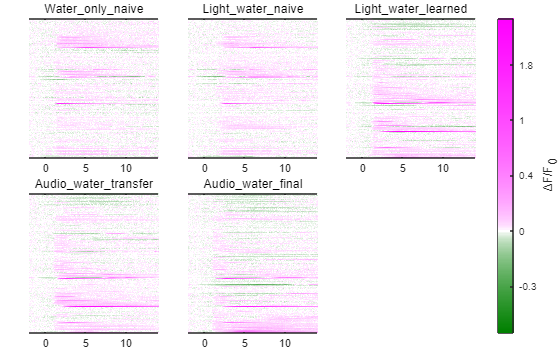

%每个泳道（组）的标题：
figure;
UniExp.LanearHeatmap(GroupNtats.NTATS,UniExp.Flags.HideYAxis,UniExp.Flags.ScaleColor,ImagescStyle={'XData',[-2,14]},Layout=tiledlayout(2,3,TileSpacing='tight',Padding='tight'));
CB=colorbar;
CB.Layout.Tile='east';
CB.Label.String='ΔF/F_0';
CB.TickLabels=round(2.^str2double(CB.TickLabels)-1,1);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);

## NTATS PCA 分析

### PCA时间线分析

PcaTable=UniExp.LinearPca(GroupNtats.NTATS,3);
PcaLines=PcaTable.Score;

PcaLines：主成分×时间×分组，可据此作图

作图。

SampleRate=8;
Markers=table;

关键时点突出显示：

Markers.Index=[3;4;6]*SampleRate+1;

关键时点符号

Markers.Shape=('o^s')';

作图

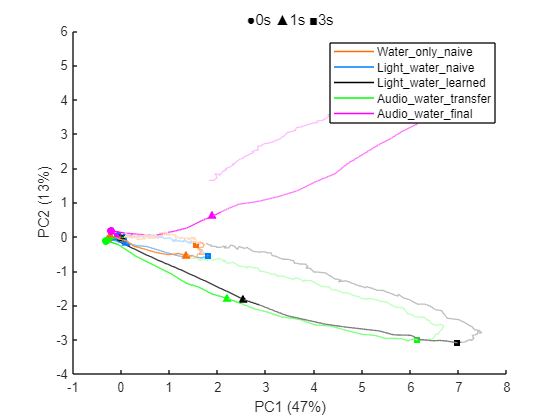

figure;
Lines=UniExp.SegmentFadePlot(table(permute(PcaLines.Data,[3,1,2]),'VariableNames',"Points"),Markers,PatchArguments={'LineWidth',1});
legend(Lines,PcaLines.Dimensions.IndexNames{3},Interpreter='none');
xlabel(sprintf('PC1 (%.2g%%)',PcaTable.Explained(1)));
ylabel(sprintf('PC2 (%.2g%%)',PcaTable.Explained(2)));
zlabel(sprintf('PC3 (%.2g%%)',PcaTable.Explained(3)));
title('●0s ▲1s ■3s')

### PCA分组点分析

[Coeff,Score,Explained]=UniExp.PointPca(GroupNtats.NTATS.Data,3,3);

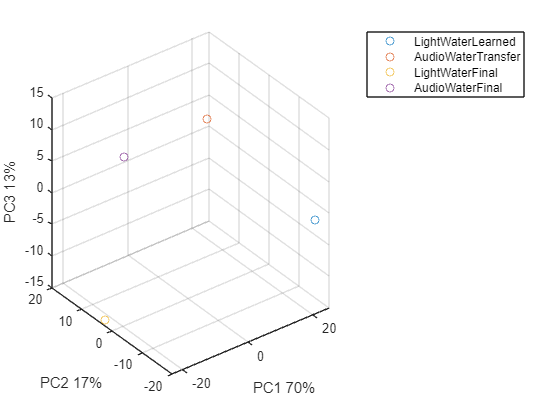

NumGroups=size(GroupNtats.NTATS,3);
Points=gobjects(NumGroups,1);
figure;
Points(1)=scatter3(Score(1,1),Score(1,2),Score(1,3));
hold on
for G=2:NumGroups
	Points(G)=scatter3(Score(G,1),Score(G,2),Score(G,3));
end
legend(Points,GroupNtats.NTATS.Dimensions.IndexNames{3});
xlabel(sprintf('PC1 %.2g%%',Explained(1)));
ylabel(sprintf('PC2 %.2g%%',Explained(2)));
zlabel(sprintf('PC3 %.2g%%',Explained(3)));

Coeff热图

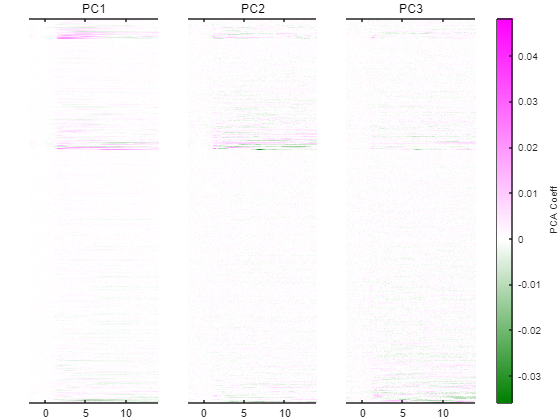

UniExp.LanearHeatmap(UniExp.HeatmapSort(permute(Coeff,[2,1,3]),UniExp.Flags.AbsMax),UniExp.Flags.HideYAxis,ImagescStyle={'XData',[-2,14]},SubTitles=["PC1","PC2","PC3"],Layout=tiledlayout(1,3,TileSpacing='tight',Padding='tight'));
CB=colorbar;
CB.Layout.Tile='east';
CB.Label.String='PCA Coeff';

## 原始航迹

### 视频

先获取你要生成视频的细胞信息

%此示例取PCA成分1中绝对系数最大的细胞
[~,CellUID]=max(abs(PcaTable.Coeff(1,:)));
CellUID=GroupNtats.CellUID(CellUID);
CellProfile=table2struct(DataSet.TableQuery(["ZLayer","CellIndex","Center","Radius"],CellUID=CellUID));

再获取回合信息

%此示例取 Naive Learned Transfer 三个阶段归一化信号值最大的回合
VideoQT=UniExp.ReadQueryTable("\\Data-Server-1\个人数据\张天夫\202308\查询表.xlsx",'原始视频');
VideoQT.CellUID(:)=CellUID;
Trials=DataSet.QueryNTS(VideoQT,UniExp.Flags.log2FdF0,1:24);
MaxTrial=struct;
for Field=string(fieldnames(Trials)')
	[~,Row]=MATLAB.DataFun.MaxSubs(Trials.(Field).TrialSignal);
	MaxTrial.(Field)=Trials.(Field).TrialUID(Row);
end
Cells=struct2cell(MaxTrial);
TrialQT=table(fieldnames(MaxTrial),vertcat(Cells{:}),'VariableNames',["GroupName","TrialUID"]);
Query=DataSet.TableQuery(["Mouse","DateTime","SampleTime"],TrialQT);
TrialProfile=struct2cell(Query);
TrialProfile=vertcat(TrialProfile{:});
TrialProfile.GroupName=fieldnames(Query);

根据回合信息，手动找到对应的Tiff文件

[~,Index]=ismember(["Naive","Learned","Transfer"],TrialProfile.GroupName);
TrialProfile.TiffPath(Index)=[
	"\\Data-Server-1\个人数据\张天夫\202305\处理分析\yqn1154\yqn1154.202304121014.AudioWater.18%350V32%350V.变换.tif"
	"\\Data-Server-1\个人数据\张天夫\202305\处理分析\yqn1154\yqn1154.202304150934.AudioWater.20%470V35%510V.变换.tif"
	"\\Data-Server-1\个人数据\张天夫\202305\处理分析\yqn1154\yqn1154.202304152249.LightWater.15%380V20%380V.变换.tif"
	];

生成视频

ZLayer=char(string(CellProfile.ZLayer));
ZLayer=ZLayer(end)=='5';
for V=1:height(TrialProfile)
	TiffPath=TrialProfile.TiffPath(V);
	[~,Filename]=fileparts(TiffPath);
	%先设置输出路径
	OutputPath=fullfile('\\Data-Server-1\组会PPT\张天夫\202310',Filename);
	SampleTime=TrialProfile.SampleTime{V};
	UniExp.CellTrialVideo(TiffPath,Z=ZLayer,TSS=struct(Start=SampleTime(1)-1,Size=numel(SampleTime)),ROI=table(CellProfile.Center{:,:}',CellProfile.Radius{:,:}','VariableNames',["Center","Radius"],'RowNames',["X","Y"]),Window=struct(Size=100),ShowSeconds=struct(Range=[-3,12],Size=20),OutputPath=OutputPath);
end

### 线图

获取每个回合的信号值，额外返回TrialRI作为不同鼠间回合统一标准，只取前8回合

GroupNts=DataSet.QueryNTS(QueryTable,UniExp.Flags.log2FdF0,1:24,ExtraColumns="TrialRI");

FieldNames=fieldnames(GroupNts);
NumGroups=numel(FieldNames);
[GroupCtt,Data3D]=deal(struct);
TimeLength=width(GroupNts.(FieldNames{1}).TrialSignal);
%选择一个分组的PC1系数前20细胞作图
PcaCoeff=table(GroupNtats.CellUID,PcaTable.Coeff(1:2,:)','VariableNames',["CellUID","Coeff"]);
[Max20,MaxIndex]=maxk(PcaCoeff.Coeff(:,1),20);
CellUID=PcaCoeff.CellUID(MaxIndex);
for G=1:NumGroups
	NTS=GroupNts.(FieldNames{G});
	NTS(NTS.TrialRI>8,:)=[];
	NTS.TrialGroup=NTS.TrialRI;
	NTS.TrialRI=[];
	GroupCtt.(FieldNames{G})=NTS;
	NTS(~ismember(NTS.CellUID,CellUID),:)=[];
	Data3D.(FieldNames{G})=permute(reshape(sortrows(NTS,["TrialGroup","CellUID"]).TrialSignal,[],8,TimeLength),[3,1,2]);
end

UniExp.LineArray(Data3D.Light_water_learned,XRange=[-3,14]/17);

无法识别的字段名称 "Light_water_learned"。

还可以从TIFF直接导出视频

UniExp.TiffVideo(MATLAB.UITools.OpenFileDialog(Filter='TIFF图像|*.tif;*.tiff',Title='选择TIFF图像',Multiselect=false),TStart=0,TSize=1000);

## 统计检验

只取前8回合，成分2，采样时点32:48取平均

TrialwisePca=struct;

for G=1:NumGroups
	NTS=GroupNts.(FieldNames{G});
	NTS(NTS.TrialRI>8,:)=[];
	NTS.TrialSignal=mean(NTS.TrialSignal(:,32:48),2);
	NTS.TrialGroup=NTS.TrialRI;
	NTS.TrialRI=[];
	TrialwisePca.(FieldNames{G})=UniExp.NtsMultiplyPcaCoeff(NTS,PcaCoeff).PcaScore;
end

P=UniExp.BarScatterCompare(TrialwisePca,false,table([2,3;3,4;4,5],'VariableNames',"GroupPair"));
ylim([-3.5,2.5]);

## 向量分析

只取前8回合，采样时点32:48取平均

GroupCtt=struct;
for G=1:NumGroups
	NTS=GroupNts.(FieldNames{G});
	NTS(NTS.TrialRI>8,:)=[];
	NTS.TrialSignal=mean(NTS.TrialSignal(:,32:48),2);
	NTS.TrialGroup=NTS.TrialRI;
	NTS.TrialRI=[];
	GroupCtt.(FieldNames{G})=NTS;
end
ProjectCosine=UniExp.VectorProjectCosine(GroupCtt,Reference="Light_water_learned");
ProjectCosine.Audio_water_transfer.ProjectCosine.Data

## 钙行为分析

### 0-1化行为分析

先根据标通道计算行为

[~,~,~,InconsistentBlocks]=DataSet.AddBehavior(ResponseWindow=seconds([3,4]),EventLogCheckLevel=UniExp.Flags.Ignore);

查询行为表现

Performance=DataSet.TableQuery("Behavior",QueryTable);
IsEmpty=cellfun(@isempty,struct2cell(Performance));
if any(IsEmpty)
	FieldNames=fieldnames(Performance);
	UniExp.Exceptions.No_data_found_in_group.Throw(join(FieldNames(IsEmpty),' '));
end
UniExp.BarScatterCompare(structfun(@(Table)Table.Behavior,Performance,UniformOutput=false),false);

### 连续行为强度分析

此方法直接将标通道求平均得到行为强度连续值

查询CD2通道值并取平均

Behavior=DataSet.TableQuery("TrialTags",QueryTable);
FieldNames=fieldnames(Behavior);
for B=1:numel(FieldNames)
	BB=cellfun(@(Table)Table.CD2,Behavior.(FieldNames{B}).TrialTags,UniformOutput=false);
	Behavior.(FieldNames{B})=mean([BB{:}],2);
end
Behavior=struct2table(Behavior);
LowerBound=513;
UpperBound=756;
Behavior=(Behavior-LowerBound)./(UpperBound-LowerBound);

#### 行为强度-彩线PCA

ColorMap=turbo;
LineColors=interp2(1:3,linspace(0,1,height(ColorMap)),ColorMap,repmat(shiftdim(single(1:3),-1),size(Behavior)),repmat(Behavior{:,:},1,1,3));

figure;
Scatters=UniExp.ColorfulMarkerPlot(table([permute(PcaLines.Data,[3,1,2]),permute(LineColors,[2,3,1])],'VariableNames',"PointColors"),Markers,PatchArguments={'LineWidth',1});
legend(Scatters(:,3),PcaLines.Dimensions.IndexNames{3},Interpreter='none');
colormap(ColorMap);
clim([0,1]);
CB=colorbar;
CB.Label.String='Lick probability';
title('●0s ▲1s ■3s');
xlabel(sprintf('PC1 (%.2g%%)',PcaTable.Explained(1)));
ylabel(sprintf('PC2 (%.2g%%)',PcaTable.Explained(2)));
zlabel(sprintf('PC3 (%.2g%%)',PcaTable.Explained(3)));

# 纯行为

选择数据文件

UEPaths=MATLAB.UITools.OpenFileDialog(Filter='行为记录文件|*.mat',Title='选择行为记录文件',Multiselect=true);

合并并保存

[Directory,Filename]=fileparts(UEPaths(1));
SplitName=split(Filename,'.');
DataPath=fullfile(Directory,strcat(SplitName(1),'.行为合并.UniExp.mat'));
UniExp.DataSet.Merge(UEPaths,OutputPath=DataPath);

## 舔水数据分析

DataSet=UniExp.DataSet(DataPath);

DataSet.Blocks.Performance=UniExp.EventLog2Performance(DataSet.Blocks.EventLog);
Query=DataSet.TableQuery(["Design","Mouse","DateTime","Performance"]);
Query.Group=Query.Design;
Summary=UniExp.LearningSummarize(Query,0.7);
TL=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
legend(MATLAB.Graphics.MultiShadowedLines(Summary.MeanCurve,Summary.SemCurve),string(Summary.Group),Location="southeast");
xlabel('Blocks');
ylabel('Hit rate');
title('Learning Curve');
Ax=nexttile;
UniExp.BarScatterCompare(Summary.LearnedDays{1}.Day,Summary.LearnedDays{2}.Day);
Ax.XTickLabel=Summary.Group;
title('Days spent to 70% hit');

## 喷气闭眼数据

选择闭眼记录视频

VideoPaths=MATLAB.UITools.OpenFileDialog(Filter='MP4视频|*.mp4',Multiselect=true,Title='选择闭眼记录视频');

作视频平均图

UniExp.BatchVideoMean(VideoPaths);

用ImageJ打开每个平均图，圈出灯和眼的位置（先圈灯后圈眼），为每个平均图保存一个RoiSet文件，文件名应当和平均图文件相同，扩展名zip

然后选择这些zip文件：

RoiPaths=MATLAB.UITools.OpenFileDialog(Filter='RoiSet|*.zip',Multiselect=true,Title='选择RoiSet');

执行测量，输出

UniExp.BatchVideoMeasure(VideoPaths,RoiPaths,["灯","眼"],[UniExp.Flags.Average_pixel_value,UniExp.Flags.Bright_area_ratio]);

选择输出的UniExp文件

UEPath=MATLAB.UITools.OpenFileDialog(Filter='行为记录文件|*.mat',Title='选择行为记录文件');

设置条件刺激和非条件刺激相对于回合开始的时间秒数。

%回合开始到条件刺激开始的秒数
CStartTime=1;
%回合开始到条件刺激结束的秒数。建议多加0.1s作为摄像头白平衡时间。
CEndTime=1.3;
%回合开始到非条件刺激开始的秒数
UStartTime=2;

拆分回合，判定行为

DataSet=UniExp.DataSet(UEPath);
[Trials,TrialSignals]=UniExp.SignalSplitTrial(DataSet.TableQuery(["BlockUID","CellUID","SampleRate","CellType","BlockSignal"]),[-CStartTime,UStartTime-CStartTime+1],"灯");
Query=MATLAB.DataTypes.Select(["TrialUID","TrialSignal"],{TrialSignals,DataSet.Cells},CellType="眼");
Behavior=UniExp.TrialSignal2Behavior(Query.TrialSignal,DataSet.TableQuery("SampleRate").SampleRate(1),CStartTime,CEndTime,UStartTime);
[~,IT,IQ]=intersect(Trials.TrialUID,Query.TrialUID);
Trials.Behavior(IT)=Behavior(IQ);
DataSet.Trials=MATLAB.DataTypes.MergeTables(DataSet.Trials,Trials);
DataSet.TrialSignals=MATLAB.DataTypes.MergeTables(DataSet.TrialSignals,TrialSignals);
save(UEPath,'DataSet');

# 从Rdc2取得UniExp

因为需要识别文件名中的字段，首先需要设置文件名中应当忽略的无效字段

UniExp.Rdc2IgnoreKeywords(["data" "pre" "adjust2" "day1" "rdc2" "long"]);

只需要设置一次，会自动保存到临时文件中

下面可从Rdc2数据路径取得UniExp数据结构。路径可以是数据文件路径的字符串向量，也可以是单个存放了数据文件的目录。如果是目录，注意目录下不能有不符合文件名规范的mat文件

DataSet = UniExp.Rdc2DataSet("C:\Users\vhtmf\Documents\空间位置\数据");

# 查询UniExp表

UniExp的6张表实际上构成了一个结构良好的关系数据库。除了使用一般的表格操纵方法外，还可以使用MATLAB扩展中的Select方法实现类似于SQL的查询：

Result=MATLAB.DataTypes.Select({DataSet.DateTimes,DataSet.Blocks,DataSet.Trials,DataSet.TrialSignal},["Design" "CellUID" "TrialSignal" "SampleRate"],Design=["blue" "blue_air"]);

# 从MBSC查找脑区的最佳注射位点

此处以查找初级听皮层（Au1）5层为例，输入参数应从MBSC查得

APRange=UniExp.BrainAP.FromInteraural([1.64,0.16]);
MLRange=[3.6,4.25];
[Center,CoronalRanges,SagittalRanges,Exception]=UniExp.CerebrumMapping(APRange,MLRange)

输入最靠近 AP=Interaural+0.900 位置的前一张和后一张冠状切片中的目标脑区ML范围，用 <B/I><AP>,<Medial>,<Lateral> 表示。如 B-1.56,0.2,3.5 表示 AP=Bregma-1.56,ML=0.2~3.5 。如果存在恰好相同AP的切片，可以只输入那一个切片的目标脑区ML范围。
输入最靠近 ML=3.925 位置的中一张和侧一张矢状切片中的目标脑区AP范围，用 <ML>,<B/I><Anterior>,<B/I><Posterior> 表示。如 0.2,B+1.56,I-1 表示 ML=0.2,AP=Bregma+1.56~Interaural-1 。如果存在恰好相同ML的切片，可以只输入那一个切片的目标脑区AP范围。


Center = 包含以下字段的 struct :
    AP: [1×1 UniExp.BrainAP]
    ML: 3.9250


CoronalRanges = 2×3 table
     AP     Medial    Lateral
    ____    ______    _______

       1     3.75        4   
    0.88      3.5        4   


SagittalRanges = 2×3 table
     ML     Anterior    Posterior
    ____    ________    _________

    3.72      1.5          0.5   
    4.25      1.1          1.1   



Exception = 

  0×0 MException 数组 - 属性:

    identifier
    message
    cause
    stack
    Correction



如果出错，可以运行此节以免重复输入：

[Center,CoronalRanges,SagittalRanges,Exception]=UniExp.CerebrumMapping(UniExp.BrainAP.FromInteraural(APRange),MLRange,CoronalRanges=CoronalRanges,SagittalRanges=SagittalRanges,Optimize=1)

Center = 包含以下字段的 struct :
    AP: [1×1 UniExp.BrainAP]
    ML: 3.8479


CoronalRanges = 2×3 table
     AP     Medial    Lateral
    ____    ______    _______

       1     3.75        4   
    0.88      3.5        4   


SagittalRanges = 2×3 table
     ML     Anterior    Posterior
    ____    ________    _________

    3.72      1.5          0.5   
    4.25      1.1          1.1   



Exception = 

  0×0 MException 数组 - 属性:

    identifier
    message
    cause
    stack
    Correction



# 序列分析

CellTrialTimes=rand(25,5);
UniExp.FindSequence(CellTrialTimes,1)

ans =      4     4    12    12    21    21
    15    15    15    15    15    15
    24    24    24    24    24    24
     6    10     6    10     6    10
